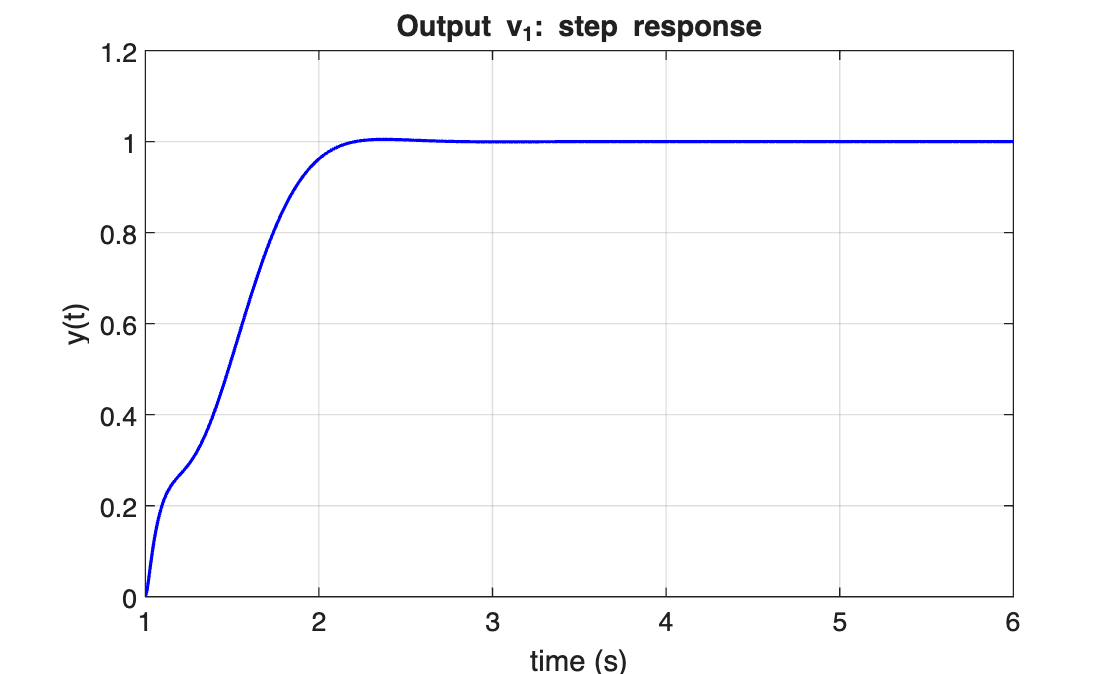

clc; clearvars; close all;

%% 参数
k = 2.0; R = 100.0; r = 0.02; M = 1.0; K = 40.0;

An = [0, -1, 1; K/M, -k^2/(r^2*R*M), 0; -K/M, 0, 0];
Bn = [0; k/(r*R*M); 0];
Cn = [0, 1, 0];

%% 增广系统
A_ic = [0, Cn; zeros(3,1), An];
B_ic = [0; Bn];

%% 极点配置
dum = [-99.6, -4+4j, -4-4j, -5];
K_ic = acker(A_ic, B_ic, dum);

%% 前向通道（同文档）
Adum = An - Bn * K_ic(2:4);
Abig = [zeros(1,4); Bn, Adum];
Bbig = [K_ic(1); zeros(3,1)];
Cbig = [0, Cn];
Dbig = 0;

Gbig = ss(Abig, Bbig, Cbig, Dbig);
Tbig = feedback(Gbig, 1, -1);  % 单位负反馈闭环

%% 时间轴（阶跃从 t=1 开始，模拟文档中偏移）
tt = 0:0.01:5;

%% Figure 1：输出 y(t) = v1 的阶跃响应
[y1, t1, x1_traj] = step(Tbig, tt);

figure(1);
plot(t1 + 1, y1, 'b', 'LineWidth', 1.2);
grid on;
xlabel('time (s)'); ylabel('y(t)');
title('Output v_1: step response');
ylim([0, 1.2]);

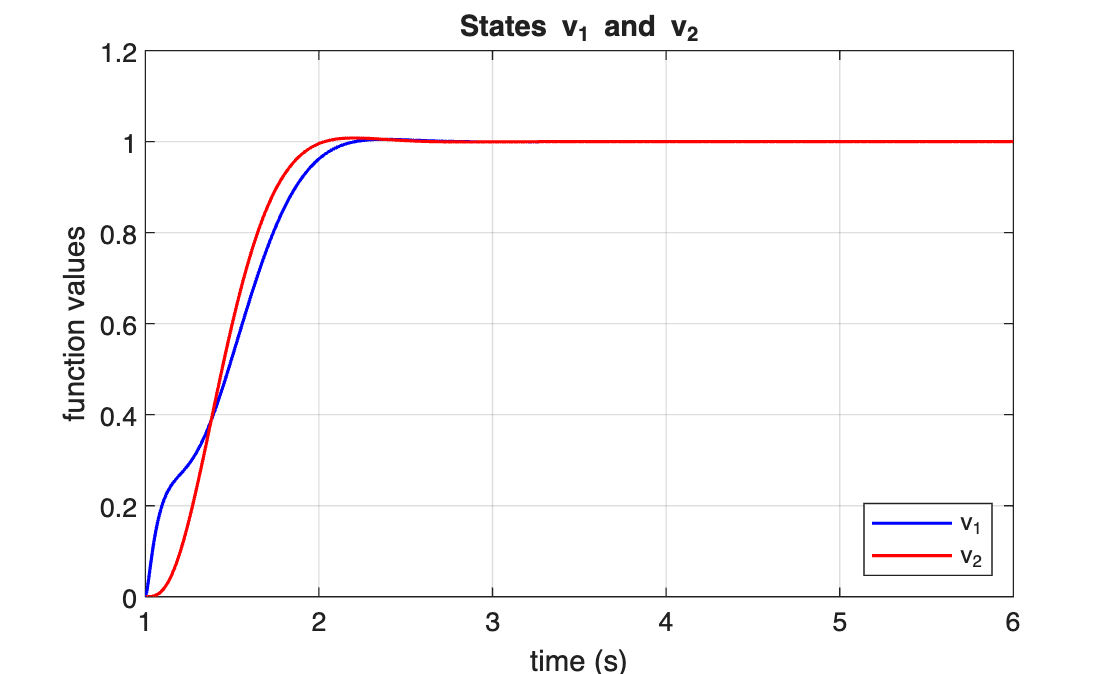


%% Figure 2：状态 x2=v1, x3=v2 的轨迹
% x1_traj 列顺序: [x_I, Delta, v1, v2] -> 列3=v1, 列4=v2
figure(2);
plot(t1 + 1, x1_traj(:, 3), 'b', 'DisplayName', 'v_1', 'LineWidth', 1.2);
hold on;
plot(t1 + 1, x1_traj(:, 4), 'r', 'DisplayName', 'v_2', 'LineWidth', 1.2);
hold off;
grid on;
xlabel('time (s)'); ylabel('function values');
legend('location', 'southeast');
title('States v_1 and v_2');

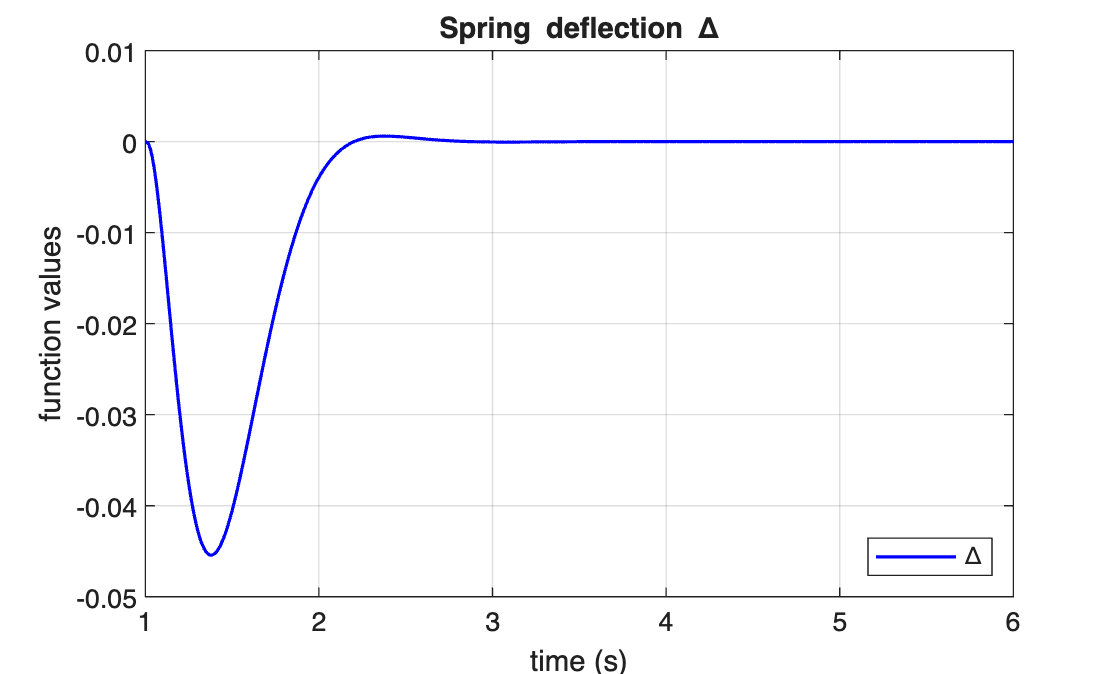


%% Figure 3：弹簧压缩量 Delta = x1 (列2)
figure(3);
plot(t1 + 1, x1_traj(:, 2), 'b', 'DisplayName', '\Delta', 'LineWidth', 1.2);
grid on;
xlabel('time (s)'); ylabel('function values');
legend('location', 'southeast');
title('Spring deflection \Delta');

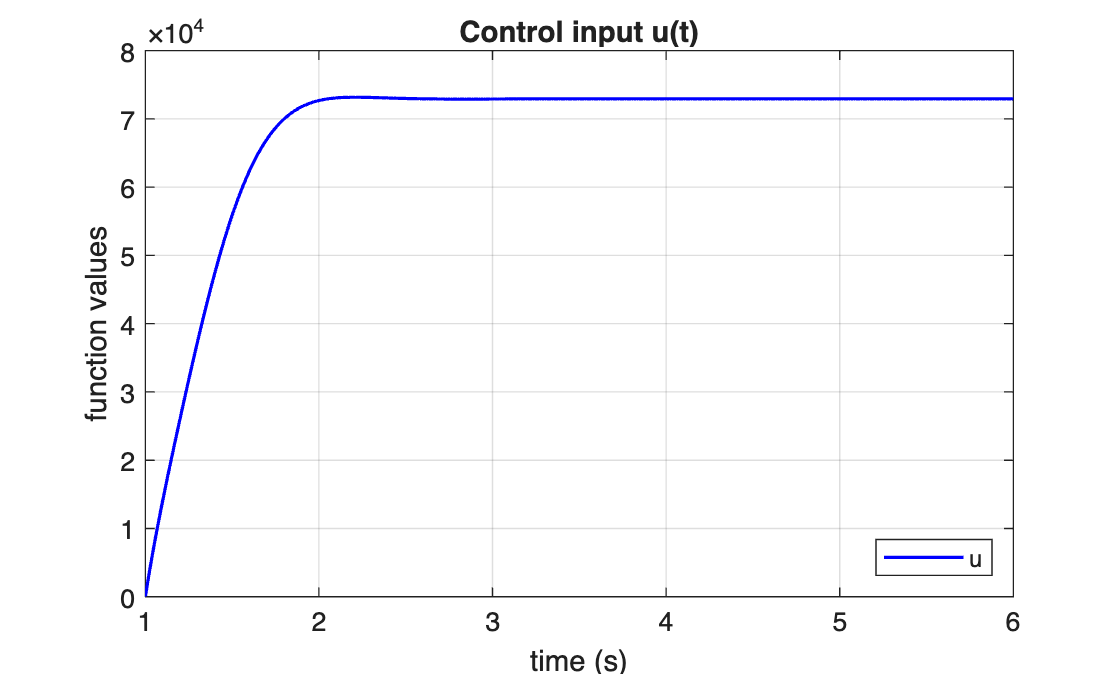


%% Figure 4：控制输入 u(t)
% u = K1*xI - K0*x，用状态轨迹重构
% Tbig 的状态是 [xI, Delta, v1, v2]
% 参考输入 r=1（单位阶跃），误差 e = r - y
% 但更直接：u = K1*x_I - K0*[x_p]，从状态轨迹计算
r_ref = ones(size(t1));        % 单位阶跃参考
xI   = x1_traj(:, 1);         % 积分状态
xp   = x1_traj(:, 2:4);       % 植物状态 [Delta, v1, v2]
u_reconstructed = K_ic(1) * xI - K_ic(2:4) * xp'; % 1×N
% 注意：反馈律 u = K1*xI - K0*x，这里 xI 是误差积分
% 实际上 Tbig 的输入是 -e，需核对符号
% 等价写法：直接用 lsim 获取状态
u_reconstructed = (K_ic(1) * xI - (K_ic(2:4) * xp')')';

figure(4);
plot(t1 + 1, u_reconstructed, 'b', 'DisplayName', 'u', 'LineWidth', 1.2);
grid on;
xlabel('time (s)'); ylabel('function values');
legend('location', 'southeast');
title('Control input u(t)');